# **Práctica 6: Sistemas diferenciales**

**Integrantes:**

Contreras Avilés Citlali Anahí

Gallegos Ruiz Diana Abigail

Morgado Reséndiz Lisardo René

Ramírez Aniceto Lauro Alexis

Rojas Gómez Ian

**PROFESOR:** Rafael Martínez Martínez

**GRUPO:** 2TV1

Antes de comenzar la práctica, hacemos unas configuraciones iniciales para la función de Heaviside.

sympref('HeavisideAtOrigin', 1);

## 1.- Se muestra la función de transferencia H(S) y 2.- Respuesta al Impulso de la función insertada.

clc; close all; clear all;
syms t s
[hs, yI] = laplaceTransImpul([3 3 1],[1,-1],cos(2*t)*heaviside(t),10);

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                     2
3 Y(s) + 3 s Y(s) + s  Y(s)

=
X(s) - s X(s)

 
DESPEJAMOS Y(s)
 
Y(s)=
  X(s) (s - 1)
- ------------
   2
  s  + 3 s + 3

 
Podemos observar que ya se tiene la funcion de transferencia
 
H(s)=
      s - 1
- ------------
   2
  s  + 3 s + 3

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
      s - 1
- ------------
   2
  s  + 3 s + 3

 
Aplicamos transformada inversa, asi la respuesta al impulso es
 
y(t)=
              /                               / sqrt(3) t \   \
              |                    sqrt(3) sin| --------- | 5 |
    /   3 t \ |    / sqrt(3) t \              \     2     /   |
-exp| - --- | | cos| --------- | - -------------------------- |
    \    2  / \    \     2     /                3             /



Muestra la respuesta al impulso

## **3.- Muestra la respuesta a entrada cero (simbólico, gráfica)**

sympref('HeavisideAtOrigin', 1);
syms t
valueEntCero = laplace2016a([3 3 1],[0,0],[1,1],cos(2*t)*heaviside(t),10);

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
0

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
0

 
DESPEJAMOS Y(s)
 
Y(s)=
    s + 4
------------
 2
s  + 3 s + 3

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
    s + 4
------------
 2
s  + 3 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
             /                               / sqrt(3) t \   \
             |                    sqrt(3) sin| --------- | 5 |
   /   3 t \ |    / sqrt(3) t \              \     2     /   |
exp| - --- | | cos| --------- | + -------------------------- |
   \    2  / \    \     2     /                3             /



## 4.- Muestra la respuesta a estado cero (simbólico, gráfica)

sympref('HeavisideAtOrigin', 1);
syms t
valueEstCero = laplace2016a([3 3 1],[1,-1],[0,0],cos(2*t)*heaviside(t),10);

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                     2
3 Y(s) + 3 s Y(s) + s  Y(s)

=
X(s) - s X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                     2
3 Y(s) + 3 s Y(s) + s  Y(s)

=
            2
   s       s
------ - ------
 2        2
s  + 4   s  + 4

 
DESPEJAMOS Y(s)
 
Y(s)=
            s (s - 1)
- ----------------------------
   4      3      2
  s  + 3 s  + 7 s  + 12 s + 12

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
  13 s    6    13 s    8
  ---- - --    ---- - --
   37    37     37    37
------------ - ---------
 2                2
s  + 3 s + 3     s  + 4

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
                                        /                               / sqrt(3) t \    \
                                        |                    sqrt(3) sin| --------- | 17 |
                              /   3 t \ |    / sqrt(3) t \              \     2     /    |
                  

## 5.- Muestra la respuesta total (Simbólico, gráfica)

valueRespTotal = laplace2016a([3 3 1],[1, -1],[1,1],cos(2*t)*heaviside(t),10);

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
X(s) - s X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
            2
   s       s
------ - ------
 2        2
s  + 4   s  + 4

 
DESPEJAMOS Y(s)
 
Y(s)=
     3      2
    s  + 3 s  + 5 s + 16
----------------------------
 4      3      2
s  + 3 s  + 7 s  + 12 s + 12

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
 50 s   142    13 s    8
 ---- + ---    ---- - --
  37     37     37    37
------------ - ---------
 2                2
s  + 3 s + 3     s  + 4

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
                                        /                               / sqrt(3) t \    \
                                        |                    sqrt(3) sin| --------- | 67 |
                              /   3 t \ |    / sqrt(3) t \              \ 

## 6.- Muestra la respuesta total al escalón con condiciones iniciales 0 (Simbólico, gráfica)

valueRespEsc = fourier2016a([3 3 1],[1,-1],heaviside(t),10);

 
APLICAMOS TRANSFORMADA DE FOURIER
 
          2
3 Y(w) - w  Y(w) + w Y(w) 3i

=
X(w) - w X(w) 1i

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
          2
3 Y(w) - w  Y(w) + w Y(w) 3i

=
              1i     /               1i \
pi dirac(w) - -- - w | pi dirac(w) - -- | 1i
               w     \                w /

 
DESPEJAMOS Y(w)
 
Y(w)=
                  1i     /               1i \
  - pi dirac(w) + -- + w | pi dirac(w) - -- | 1i
                   w     \                w /
- ----------------------------------------------
                     2
                  - w  + w 3i + 3

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(w)
 
Y(w)=
        /               1 \
  2 + w | pi dirac(w) + - | 1i - pi dirac(w)
        \               3 /                     1i
- ------------------------------------------ - ---
                   2                           3 w
                - w  + w 3i + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
/              /            

## **7. Se muestra la gráfica de las 5 respuestas**

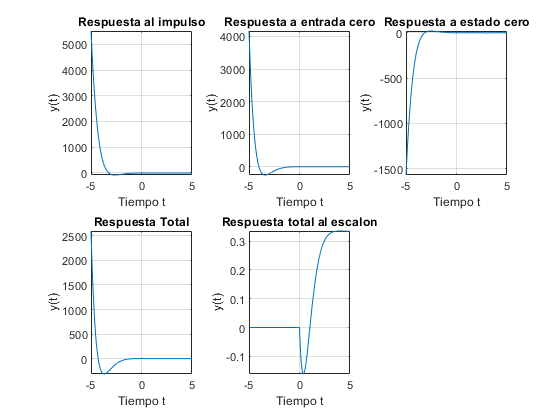

subplot(2,3,1)
fplot(yI);
title('Respuesta al impulso');
xlabel('Tiempo t');
ylabel('y(t)');
grid on;

subplot(2,3,2)
fplot(valueEntCero);
title('Respuesta a entrada cero');
xlabel('Tiempo t');
ylabel('y(t)');
grid on;

subplot(2,3,3)
fplot(valueEstCero);
title('Respuesta a estado cero');
xlabel('Tiempo t');
ylabel('y(t)');
grid on;

subplot(2,3,4)
fplot(valueRespTotal);
title('Respuesta Total');
xlabel('Tiempo t');
ylabel('y(t)');
grid on;

subplot(2,3,5)
fplot(valueRespEsc);
title('Respuesta total al escalon');
xlabel('Tiempo t');
ylabel('y(t)');
grid on;

function y = laplace2016a(a,b,ciy,xi,t0)
% a coeficientes de las derivadas de la salida menor a mayor [a_0, ..., a_n]
% b coeficientes de las derivadas de la entrada menor a mayor [b_0, ..., b_m]
% ciy condiciones iniciales de la salida de  menor a mayor [y(0), y(0)^(n-1)]
% xi función de entrada en terminos de la variable simbolica t previamente
% declarada en el command window
% t0 tiempo final para graficar la solucion, la derivada, y la segunda 
% derivada 
% ejemplo: resolver y^(3)+y^(2)+2y^(1)+2y=3x^(2)-x^(1)+2x con y^(2)(0)=1 y^(1)=3
% y(0)=2, x(t)=exp(-t)cos(t)u(t), para 10 segundos, se resuleve como
% syms t
% laplace2016a([2 2 1 1],[2 -1 3],[2 3 1],exp(-t)*cos(t)*heaviside(t),10)
close all
tam=size(a);
tami=size(b);
syms y(t) Y(s) x(t) X(s) Yy fp;
syms edd edi 
edd=0;
edi=0;

for i=1:tam(2)
   edd=edd+a(i)*s^(i-1)*Y(s);
   for k=1:i-1
       edd=edd-a(i)*(s^(i-1-k)*ciy(k));
   end
end

for i=1:tami(2)
   edi=edi+b(i)*s^(i-1)*X(s);
   %for k=1:i-1
     %  edi=edi-b(i)*(s^(i-1-k)*cix(k));
   %end
end
mensaje('APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales')

pretty(edd)
disp('=')
pretty(edi)

mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

edi=subs(edi,X(s), laplace(xi));
pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(s)')

edd=collect(edd,Y(s));
edd=subs(edd,Y(s),Yy);
eq1=edd==edi;
disp('Y(s)=')
edd=solve(eq1, Yy);
pretty(simplify(edd))

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)')
disp('Y(s)=')
pretty(partfrac(edd))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores

mensaje('Aplicamos transformada inversa, asi la solución es')
disp('y(t)=')
y(t)=ilaplace(edd);
pretty(y(t))
y = y(t);
end

function mensaje(texto)
disp( ' ')
disp(texto)
disp( ' ')
end

function f = fourier2016a(a,b,xi,t0)
% a coeficientes de las derivadas de la salida menor a mayor [a_0, ..., a_n]
% b coeficientes de las derivadas de la entrada menor a mayor [b_0, ..., b_m]
% xi función de entrada en terminos de la variable simbolica t previamente
% declarada en el command window
% t0 tiempo final para graficar la solucion, la derivada, y la segunda 
% derivada 
% ejemplo: resolver y^(2)+2y^(1)+2y=x^(1)+2x con y^(1)(0)=0
% y(0)=0, x(0)=0, x(t)=exp(-t)u(t), para 5 segundos, se resuleve como
% syms t
% fourier2016a([2 2 1],[2 1],exp(-t)*heaviside(t),5)
close all
tam=size(a);
tami=size(b);
syms y(t) Y(w) x(t) X(w) Yy fp;
syms edd edi 
edd=0;
edi=0;

for i=1:tam(2)
   edd=edd+a(i)*(j*w)^(i-1)*Y(w);
end

for i=1:tami(2)
   edi=edi+b(i)*(j*w)^(i-1)*X(w);  
end
mensaje('APLICAMOS TRANSFORMADA DE FOURIER')

pretty(edd)
disp('=')
pretty(edi)

mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

edi=subs(edi,X(w), fourier(xi));
pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(w)')

edd=collect(edd,Y(w));
edd=subs(edd,Y(w),Yy);
eq1=edd==edi;
disp('Y(w)=')
edd=solve(eq1, Yy);
pretty(edd)

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(w)')
disp('Y(w)=')
pretty(partfrac(edd))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores
 
mensaje('Aplicamos transformada inversa, asi la solución es')
disp('y(t)=')
y(t)=ifourier(edd,t);
pretty(y(t))
f = y(t);
end

function [hs, yI] = laplaceTransImpul(a,b,xi,t0)
% a coeficientes de las derivadas de la salida menor a mayor [a_0, ..., a_n]
% b coeficientes de las derivadas de la entrada menor a mayor [b_0, ..., b_m]
% ciy condiciones iniciales de la salida de  menor a mayor [y(0), y(0)^(n-1)]
% xi función de entrada en terminos de la variable simbolica t previamente
% declarada en el command window
% t0 tiempo final para graficar la solucion, la derivada, y la segunda 
% derivada 
% ejemplo: resolver y^(3)+y^(2)+2y^(1)+2y=3x^(2)-x^(1)+2x con y^(2)(0)=1 y^(1)=3
% y(0)=2, x(t)=exp(-t)cos(t)u(t), para 10 segundos, se resuleve como
% syms t
% laplace2016a([2 2 1 1],[2 -1 3],[2 3 1],exp(-t)*cos(t)*heaviside(t),10)
close all
tam=size(a);
tami=size(b);
syms y(t) Y(s) x(t) X(s) Yy fp;
syms edd edi 
edd=0;
edi=0;

for i=1:tam(2)
   edd=edd+a(i)*s^(i-1)*Y(s);
end

for i=1:tami(2)
   edi=edi+b(i)*s^(i-1)*X(s);
   %for k=1:i-1
     %  edi=edi-b(i)*(s^(i-1-k)*cix(k));
   %end
end
mensaje('APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales')

pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(s)')

edd=collect(edd,Y(s));
edd=subs(edd,Y(s),Yy);
eq1=edd==edi;
disp('Y(s)=')
edd=solve(eq1, Yy);
pretty(simplify(edd))

mensaje('Podemos observar que ya se tiene la funcion de transferencia')

edd = subs(edd, X(s), 1);
disp('H(s)=')
pretty(simplify(edd))

hs = edd;

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)')
disp('Y(s)=')
pretty(partfrac(edd))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores

mensaje('Aplicamos transformada inversa, asi la respuesta al impulso es')
disp('y(t)=')
y(t)=ilaplace(edd);
pretty(y(t))
yI = y(t);

end